# **WM9QE: Applied Statistics for Artificial Intelligence**

## **Synthetic Data **

This MATLAB Live Script is a suppliment to the Data Collection, Sampling, and Synthetic Data session. Full detail of the lectures and examples are availabe on [Section: Week One | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=576666). 

Learning Objectives

- Explain the conceptual principles behind the approaches.

- Understand and implement various synthetic data techniques in MATLAB, providing practical workflows for creating realistic synthetic datasets.

Overview

This tutorial provides hands-on experience with the synthetic data generation techniques covered in the theoretical session: *Distribution-based* and *Simulation-based* methods. Synthetic data plays an increasingly critical role in modern AI systems, where access to real datasets may be restricted due to privacy regulations, limited availability, or cost constraints. By generating artificial yet statistically consistent data, practitioners can train, validate, and stress-test machine learning models in a controlled environment.

# Section 1: Distributed-based Synthetic Data

## **1.1. Overview**

Synthetic data refers to artificially generated data that imitates the statistical or behavioural properties of real-world datasets. It is widely used when access to authentic data is limited due to privacy, cost, or availability constraints. By simulating data generation processes, researchers and engineers can test algorithms, validate models, and explore hypothetical scenarios without depending on sensitive or proprietary information.

Two broad approaches to synthetic data generation are:

- **Distribution-based synthetic data** – samples are drawn from fitted statistical distributions that describe the patterns and variability of the observed data.

- **Simulation-based synthetic data** – data are generated by simulating a process or system governed by physical laws, probabilistic models, or behavioural rules.

**Advantages**

- Enables experimentation when real data are unavailable or confidential.

- Facilitates model validation under controlled conditions.

- Allows scalable data generation with defined statistical properties.

**Limitations**

- May not capture complex dependencies or real-world variability.

- Risk of introducing unrealistic or biased patterns if model assumptions are oversimplified.

- Requires careful validation to ensure the generated data align with intended use cases.

**Typical applications include:**

- Algorithm prototyping and stress testing.

- Machine learning model evaluation and benchmarking.

- Simulation of physical systems, financial scenarios, or medical records.

- Privacy-preserving data sharing and teaching demonstrations.

## **1.2. Distribution-based Synthetic Data**

Distribution-based synthetic data generation assumes that the observed dataset originates from an underlying probability distribution.

The goal is to **estimate the distribution’s parameters** from real data and then **generate new samples** that preserve its essential statistical characteristics.

There are two main modelling strategies:

- **Parametric approaches:** Assume a known functional form, such as Gaussian, exponential, or beta distributions, and estimate parameters (e.g., mean and variance). These are efficient when the data approximately follow a known law.

- **Non-parametric approaches:** Make fewer assumptions about the functional form, instead relying on empirical density estimation (e.g., kernel density or histogram-based methods). These are useful when the data structure is complex or multimodal.

Distribution-based methods are suitable when:

- The data distribution is well understood or can be approximated.

- Generating statistically similar but anonymised records is desired.

- Dependencies between variables can be captured through multivariate or mixture models.

## **1.3. Gaussian (Normal) Distribution**

The Normal Distribution is a continuous probability distribution that is symmetric about the mean, showing that data near the mean are more frequent in occurrence than data far from the mean. It's often called the bell curve because of its characteristic shape.

It's defined by two parameters:

- The **mean** ($\mu $): This determines the center of the distribution.

- The **variance** ($\sigma ^2$) or its square root, the **standard deviation** ($\sigma $): This determines the spread or width of the distribution. A smaller $\sigma $ results in a narrower, taller curve, while a larger σ results in a wider, flatter curve.

Many natural phenomena, like human heights, blood pressure, and measurement errors, follow this distribution.

The probability density function (PDF) for a normal distribution is given by: 


$$f(x)=\frac{1}{\sigma \sqrt{2\pi}}e^{{-\frac{1}{2}}(\frac{x-\mu}{\sigma})^2}$$


The figure below illustrates the bell shape:

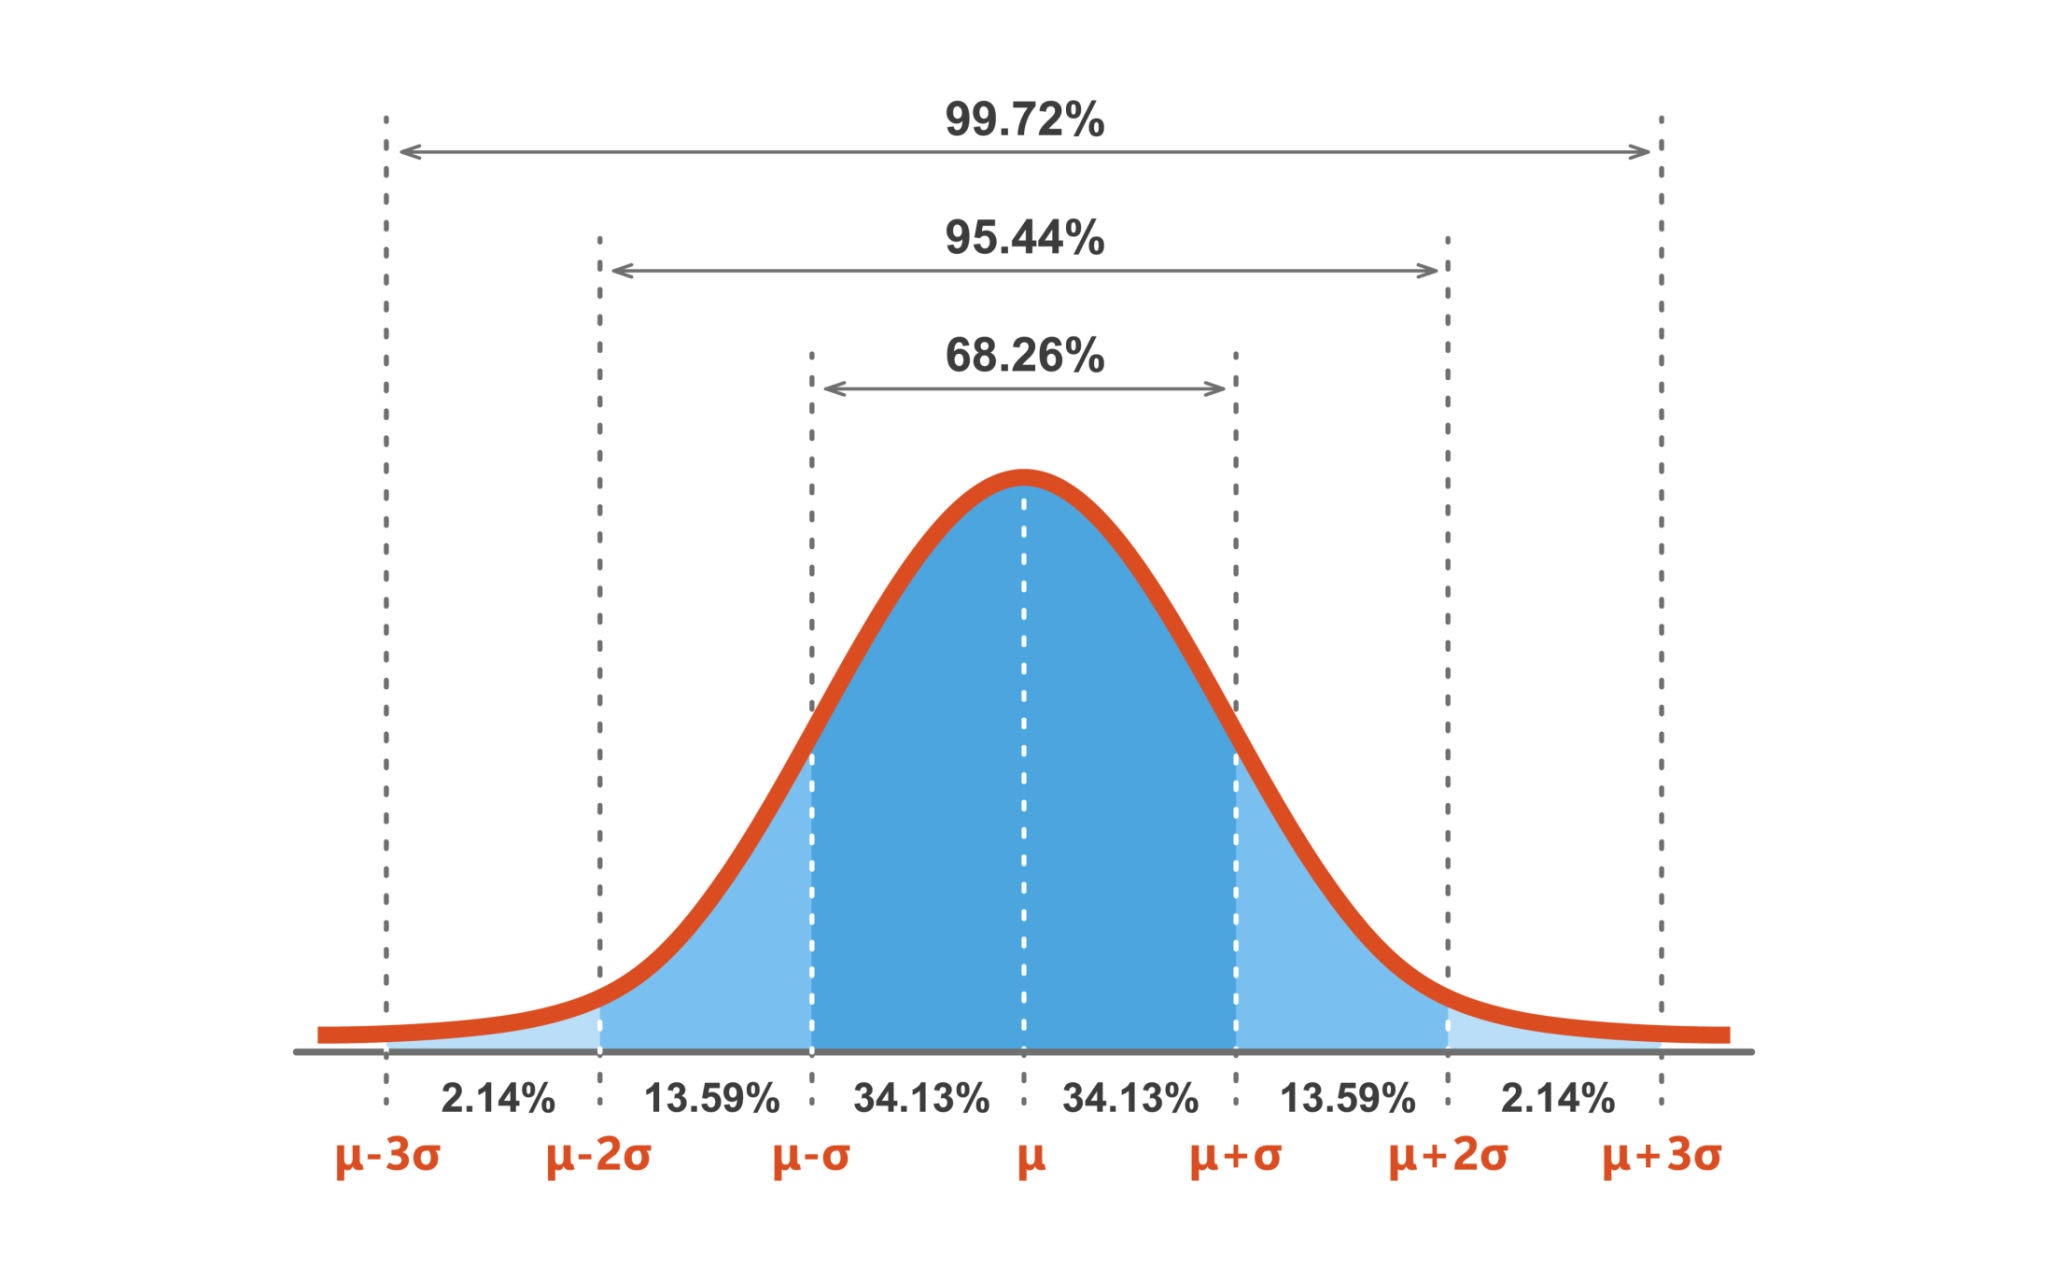

## 1.3.1. Gaussian Distribution Implementation in MATLAB

To implement a Gaussian Distribution in MATLAB, you can generate random numbers that follow the bell-shape distribution using the `randn` function (for standard normal distribution) and then scale and shift them, or use the `normrnd` function (for a specified $\mu $ and $\sigma $).

The following code generates an array of $10,000$ random numbers with a specified mean ($\mu =5$) and standard deviation ($\sigma =2$), and then visualizes its histogram to show the bell shape.

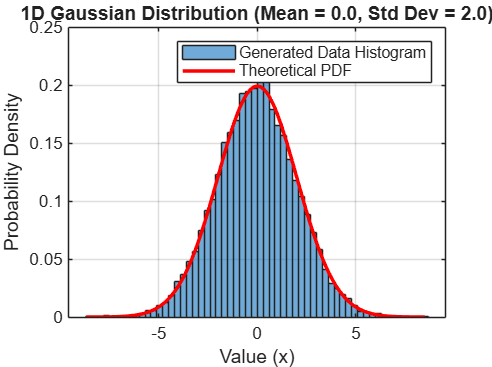

clear; clc; close all;
rng(42); %Seed define for reproducibility

% Define parameters
mu = 0;         % Mean
sigma = 2;      % Standard Deviation (sqrt(variance)=sqrt(4)=2)
N = 10000;      % Number of random samples to generate

% Generate normally distributed random numbers
% normrnd(mu, sigma, rows, cols) generates random numbers from a 
% normal distribution with mean mu and standard deviation sigma.
data_1d = normrnd(mu, sigma, N, 1);

% Create a figure to illustrate the 1D Gaussian concept
figure;
histogram(data_1d, 'Normalization', 'pdf');
hold on;

% Plot the theoretical PDF for comparison
x = linspace(min(data_1d), max(data_1d), 100);
y = normpdf(x, mu, sigma);
plot(x, y, 'r-', 'LineWidth', 2);

title(sprintf('1D Gaussian Distribution (Mean = %.1f, Std Dev = %.1f)', mu, sigma));
xlabel('Value (x)');
ylabel('Probability Density');
legend('Generated Data Histogram', 'Theoretical PDF');
grid on;

**Explanation:**

- `normrnd(mu, sigma, N, 1)`: This function generates an N×1 array (`data_1d`) of random numbers drawn from a normal distribution with the specified mean ($\mu $) and standard deviation ($\sigma $).

- `histogram(..., 'Normalization', 'pdf')`: This plots the frequency distribution of the generated data, scaled so the area under the histogram bars sums to 1, replicating the probability density function (PDF).

- `x = linspace(min(data_1d), max(data_1d), 100): `This defines the domain (the range of x values) over which the theoretical Gaussian curve will be calculated and plotted. It ranges from the minimum to the maximum value of `data_1d` with 100 evenly spaced values.

- `normpdf(x, mu, sigma)`: This calculates the theoretical PDF value for the normal distribution at each point in the vector x, allowing us to superimpose the perfect bell curve onto the histogram for comparison.

## 1.3.2. 2D Gaussian Distribution (Bivariate Normal)

A 2D Gaussian Distribution, also known as the Bivariate Normal Distribution, is an extension of the normal distribution to two variables, typically x and y. It's defined by:

- A **mean vector** $\mu =[\mu_x,\mu_y]$, where $\mu _x$ and $\mu _y$ are the means for the x and y variables, respectively.

- A **covariance matrix** $\Sigma =\left\lbrack {}^{\sigma_x^2 }_{\rho \;\sigma_x \sigma_y }^{\rho \;\sigma_x \sigma_y }_{\sigma_y^2 }\right\rbrack$

- $\sigma_x^2$ and $\sigma_y^2$ are the variances of x and y.

- $\rho$ is the correlation coefficient between x and y. If $\rho=0$, the variables are uncorrelated, and the distribution is an axis-aligned bell-shaped surface.

The resulting distribution is a **bell-shaped surface** in 3D space, which projects onto the xy-plane as elliptical or circular contours.

**MATLAB Implementation with **`mvnrnd`

The MATLAB function `mvnrnd` (Multivariate Normal Random Numbers) is used to generate random numbers from a multivariate normal distribution, which includes the 2D Gaussian as a special case.

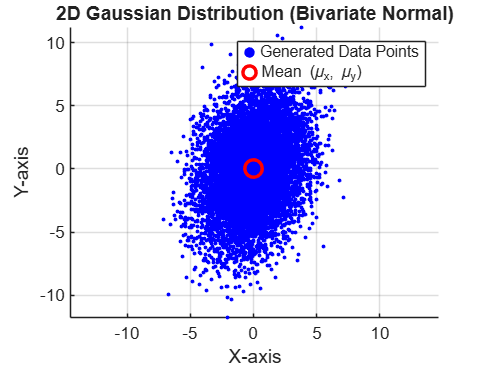

% Define parameters for 2D Gaussian
mu_2d = [0, 0];       % Mean vector [u_x, u_y]
% Covariance matrix Sigma:
% [variance_x, covariance_xy]
% [covariance_xy, variance_y]
variance_x = 4;           % Variance of X (σx²)
variance_y = 9;           % Variance of Y (σy²)
rho = 0.25;
Sigma = [variance_x, rho*sqrt(variance_x*variance_y);
         rho*sqrt(variance_x*variance_y), variance_y];
N_2d = 10000;            % Number of samples

% Generate 2D normally distributed random data
% mvnrnd(mu, Sigma, N) generates N samples from a multivariate 
% normal distribution with mean vector mu and covariance matrix Sigma.
data_2d = mvnrnd(mu_2d, Sigma, N_2d);

% Visualize the 2D distribution using a scatter plot
figure;
scatter(data_2d(:, 1), data_2d(:, 2), 5, 'b', 'filled');
hold on;
plot(mu_2d(1), mu_2d(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2); % Plot the mean

title('2D Gaussian Distribution (Bivariate Normal)');
xlabel('X-axis');
ylabel('Y-axis');
legend('Generated Data Points', 'Mean (\mu_x, \mu_y)');
axis equal;
grid on;

**Explanation of **`mvnrnd(mu_2d, Sigma, N_2d)`: 

- `mu_2d`: The **mean vector** specifies the central location of the distribution in the xy-plane. 

- `Sigma:` The **covariance matrix** dictates the orientation and spread: the diagonal elements (4 and 9) are the variances ($\sigma_x^2$ and $\sigma_y^2$), controlling the spread along the x and y axes, while he off-diagonal elements (1.5 and 1.5) are the covariance ($\rho\sigma_x\sigma_y$), controlling the tilt/rotation of the distribution. A non-zero covariance means x and y are correlated, resulting in an ellipse that's not parallel to the axes.

- `N_2d`: The number of data points to generate.

- The function returns an `N_2d`×2 matrix, where the first column contains the x-coordinates and the second column contains the y-coordinates of the random samples.

Let's look at more 2D Gaussian Distribution examples:

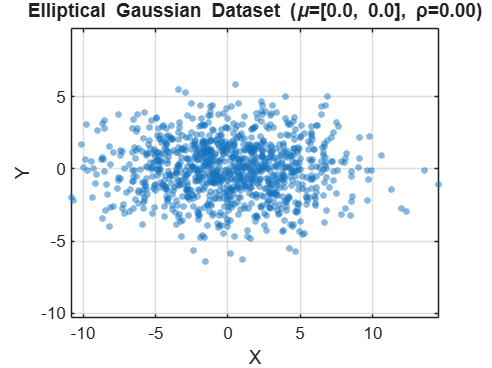

%% Bidimensional Gaussian Data Generator (Circular or Elliptical)
% Generates a 2D synthetic dataset with adjustable means, variances, and correlation

%% === Parameters (modifiable) ===
mu = [0, 0];          % Mean vector [μx, μy]
variance_x = 16;           % Variance of X (σx²)
variance_y = 4;           % Variance of Y (σy²)
rho = 0;              % Correlation between X and Y (-1 ≤ ρ ≤ 1); ρ = 0 creates a circular shape
n_samples = 1000;       % Number of samples

%% === Covariance Matrix ===
% Σ = [σx²      ρσxσy;
%       ρσxσy   σy² ]
Sigma = [variance_x, rho*sqrt(variance_x*variance_y);
         rho*sqrt(variance_x*variance_y), variance_y];

%% === Generate Data ===
data = mvnrnd(mu, Sigma, n_samples);

x = data(:,1); %x-axis distribution
y = data(:,2); %y-axis distribution

%% === Plot 1: Scatter Plot of Samples ===
figure;
scatter(x, y, 15, 'filled', 'MarkerFaceAlpha', 0.5);
title(sprintf('Elliptical Gaussian Dataset (\\mu=[%.1f, %.1f], ρ=%.2f)', mu(1), mu(2), rho));
xlabel('X');
ylabel('Y');
axis equal;
grid on;
box on;

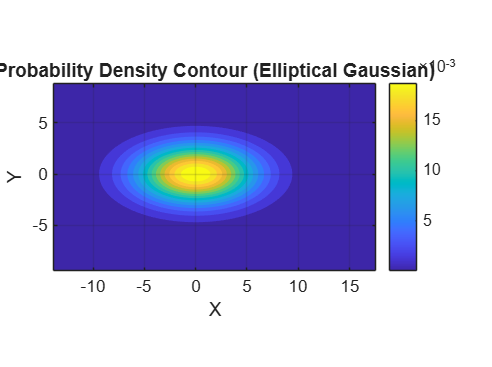


%% === Plot 2: Contour Plot of Probability Density ===
xrange = linspace(min(x)-3, max(x)+3, 150);
yrange = linspace(min(y)-3, max(y)+3, 150);
[Xgrid, Ygrid] = meshgrid(xrange, yrange);
XY = [Xgrid(:), Ygrid(:)];

pdf_vals = mvnpdf(XY, mu, Sigma);
pdf_vals = reshape(pdf_vals, size(Xgrid));

figure;
contourf(Xgrid, Ygrid, pdf_vals, 15, 'LineColor', 'none');
colorbar;
title('Probability Density Contour (Elliptical Gaussian)');
xlabel('X');
ylabel('Y');
axis equal; grid on; box on;

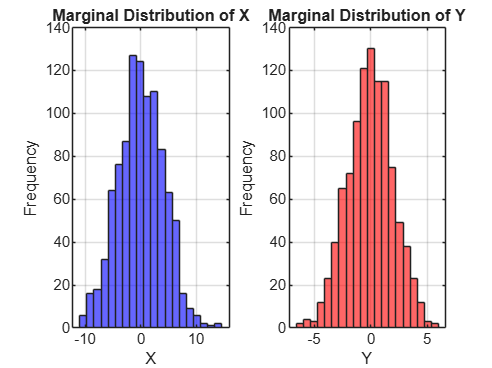


%% === Plot 3: Marginal Distributions (X and Y) ===
figure;
subplot(1,2,1);
histogram(x, 20, 'FaceColor','b', 'FaceAlpha',0.6);
title('Marginal Distribution of X');
xlabel('X'); ylabel('Frequency'); grid on;

subplot(1,2,2);
histogram(y, 20, 'FaceColor','r', 'FaceAlpha',0.6);
title('Marginal Distribution of Y');
xlabel('Y'); ylabel('Frequency'); grid on;

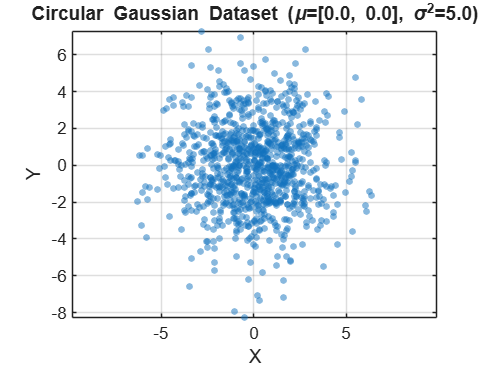

%% Bidimensional Circular Gaussian Data Generator
% Generates a 2D synthetic dataset with adjustable mean and variance

%% === Parameters (modifiable) ===
mu = [0, 0];       % Mean vector [μx, μy]
variance = 5;         % Variance (same for x and y) → circular Gaussian
n_samples = 1000;   % Number of synthetic data points

%% === Covariance Matrix (Circular Gaussian) ===
% For circular distributions: Σ = σ²I (equal variance, zero correlation)
% Where:
%   - σ² is the variance
%   - I is the identity matrix: [1 0; 0 1]
%   - eye(2) creates a 2×2 identity matrix in MATLAB
%   - This creates equal variance in X and Y directions with zero correlation
%   - Result: Σ = [σ² 0; 0 σ²] → circular (isotropic) distribution
Sigma = variance * eye(2);   % Identity scaled by variance → isotropic / circular

%% === Generate Data ===
data = mvnrnd(mu, Sigma, n_samples);

%% === Extract x and y ===
x = data(:,1);
y = data(:,2);

%% === Plot 1: Scatter plot of generated data ===
figure;
scatter(x, y, 15, 'filled', 'MarkerFaceAlpha', 0.5);
title(sprintf('Circular Gaussian Dataset (\\mu=[%.1f, %.1f], \\sigma^2=%.1f)', mu(1), mu(2), variance));
xlabel('X');
ylabel('Y');
axis equal; grid on; box on;

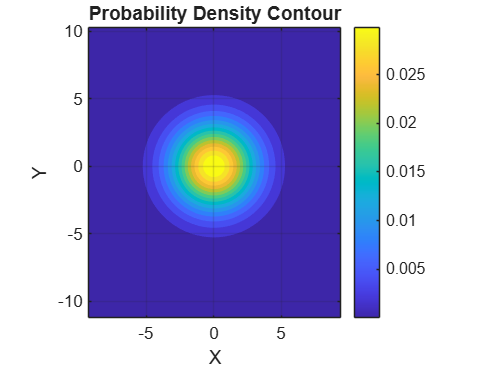


%% === Plot 2: Contour plot of probability density (optional) ===
% Define a grid around the data range
xrange = linspace(min(x)-3, max(x)+3, 100);
yrange = linspace(min(y)-3, max(y)+3, 100);
[Xgrid, Ygrid] = meshgrid(xrange, yrange);
XY = [Xgrid(:), Ygrid(:)];

% Evaluate Gaussian PDF on the grid
pdf_vals = mvnpdf(XY, mu, Sigma);
pdf_vals = reshape(pdf_vals, size(Xgrid));

figure;
contourf(Xgrid, Ygrid, pdf_vals, 15, 'LineColor', 'none');
colorbar;
title('Probability Density Contour');
xlabel('X');
ylabel('Y');
axis equal; grid on; box on;

Let's create a Mikey Mouse Shape:

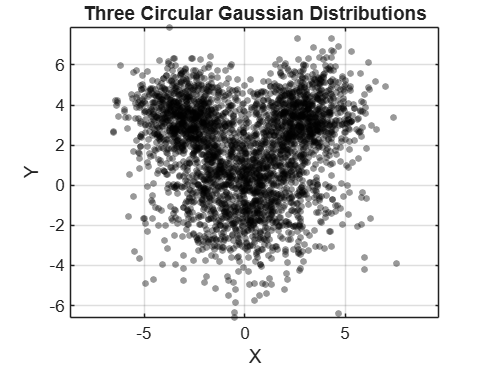

%% Mickey Mouse-like pattern with three circular Gaussians

%% === Parameters for Three Circles ===

% HEAD (large circle at bottom center)
mu_head = [0, 0];           % Center position
var_head = 4;               % Variance (σ²) - controls spread
n_head = 1500;              % Number of samples

% LEFT EAR (smaller circle at top-left)
mu_left_ear = [-3, 3.5];    % Position: left and up
var_ear = 1.44;             % Variance of both ears (smaller than head)
n_ear = 800;                % Number of samples of both ears

% RIGHT EAR (smaller circle at top-right)
mu_right_ear = [3, 3.5];    % Position: right and up
                            % Same variance and n as left ear

% TIP: Adjust variance to control cluster spread
% - SMALLER variance (e.g., 0.5, 1) → tighter, more distinct circles
% - LARGER variance (e.g., 5, 10) → more dispersed, overlapping clusters

%% === Generate Covariance Matrices (Circular) ===
Sigma_head = var_head * eye(2);
Sigma_ear = var_ear * eye(2);

%% === Generate Data for Each Circle ===
data_head = mvnrnd(mu_head, Sigma_head, n_head);
data_left_ear = mvnrnd(mu_left_ear, Sigma_ear, n_ear);
data_right_ear = mvnrnd(mu_right_ear, Sigma_ear, n_ear);

% Combine all data
data_all = [data_head; data_left_ear; data_right_ear];
x_all = data_all(:,1);
y_all = data_all(:,2);

%% === Plot 1: Scatter Plot of All Samples ===
figure;
hold on;
scatter(data_head(:,1), data_head(:,2), 15, 'k', 'filled', 'MarkerFaceAlpha', 0.4);
scatter(data_left_ear(:,1), data_left_ear(:,2), 15, 'k', 'filled', 'MarkerFaceAlpha', 0.4);
scatter(data_right_ear(:,1), data_right_ear(:,2), 15, 'k', 'filled', 'MarkerFaceAlpha', 0.4);
title('Three Circular Gaussian Distributions');
xlabel('X');
ylabel('Y');
axis equal;
grid on;
box on;
hold off;

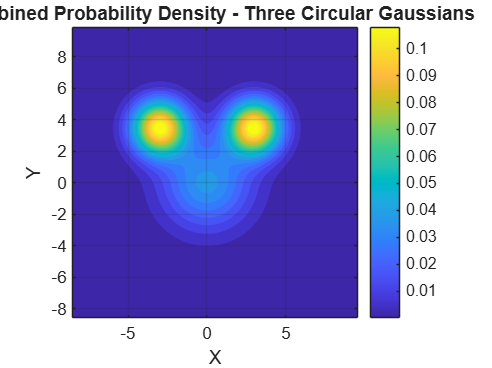


%% === Plot 2: Contour Plot of Combined Probability Density ===
xrange = linspace(min(x_all)-2, max(x_all)+2, 200);
yrange = linspace(min(y_all)-2, max(y_all)+2, 200);
[Xgrid, Ygrid] = meshgrid(xrange, yrange);
XY = [Xgrid(:), Ygrid(:)];

% Calculate combined PDF (sum of three Gaussians)
pdf_head = mvnpdf(XY, mu_head, Sigma_head);
pdf_left = mvnpdf(XY, mu_left_ear, Sigma_ear);
pdf_right = mvnpdf(XY, mu_right_ear, Sigma_ear);
pdf_combined = pdf_head + pdf_left + pdf_right;
pdf_combined = reshape(pdf_combined, size(Xgrid));

figure;
contourf(Xgrid, Ygrid, pdf_combined, 20, 'LineColor', 'none');
colorbar;
title('Combined Probability Density - Three Circular Gaussians');
xlabel('X');
ylabel('Y');
axis equal; 
grid on; 
box on;

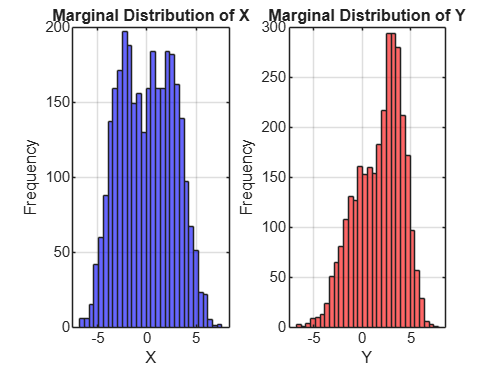


%% === Plot 3: Individual Marginal Distributions ===
figure;
subplot(1,2,1);
histogram(x_all, 30, 'FaceColor','b', 'FaceAlpha',0.6);
title('Marginal Distribution of X');
xlabel('X'); ylabel('Frequency'); grid on;

subplot(1,2,2);
histogram(y_all, 30, 'FaceColor','r', 'FaceAlpha',0.6);
title('Marginal Distribution of Y');
xlabel('Y'); ylabel('Frequency'); grid on;

## **1.4. Gaussian Mixture Model (GMM)**

The GMM is a probabilistic model that represents the probability distribution of observations as a mixture of several underlying component Gaussian distributions. It is a powerful tool for **density estimation** and **clustering**. Instead of assuming all data comes from a single Gaussian distribution (like the bell curve), a GMM assumes the data is generated from a weighted sum (a mixture) of different Gaussian distributions.

Each component Gaussian distribution, $k$, has its own set of parameters:

- **Mean (**$\mu_k$**)**: The center of the $k$-th cluster.

- **Covariance Matrix (**$\Sigma_k$**)**: The spread and orientation of the $k$-th cluster.

- **Mixing Probability (**$\phi_k$**)**: The weight or probability that a data point belongs to the $k$-th component.

The overall probability density function (PDF) of the GMM is:


$$p\left(x\right)=\sum_{k=1}^K \phi_k N\left(x\left|\mu k,\Sigma k\right.\right)$$


where $\sum_{k=1}^K \phi_k =1$.

**Concept Illustration:** A GMM is excellent at modeling data that forms distinct clusters. If you have two groups of people (e.g., short and tall) that are measured for height, the overall height distribution will be a single, non-ideal Gaussian, but a GMM with two components would accurately model the height distribution of the "short group" and the "tall group" separately, combining them into the final distribution.

## 1.4.1. Gaussian Mixture Model Implementation in MATLAB

To implement a GMM, you first need data that is actually generated from a mixture of Gaussians. Then, you use the `fitgmdist` function to estimate the parameters of the underlying components. The code below implements a GMM to learn the statistical structure of the patient multivariate dataset and then uses that learned model to generate new, synthetic data.

%% Synthetic Dataset: Complex Patterns (Using MATLAB Built-in "patients" Dataset)
% Purpose: Generate challenging patterns for algorithm validation
% This is a hybrid strategy: Generate Synthetic data and add it to
% real-world data

%% 1) Load MATLAB built-in dataset: "patients"
load patients   % Contains Age, Height, Weight, etc.

%% 2) Fit Gaussian Mixture Model with 3 components
gmm = fitgmdist([Age, Height, Weight], 3, 'RegularizationValue', 1e-6);

- Data Matrix Creation: `[Age, Height, Weight]` concatenates the three separate data vectors from patients into a single matrix. This matrix has N rows (one for each patient) and 3 columns (features: Age, Height, Weight). This makes the problem a 3D Multivariate GMM.

- `fitgmdist`**:** This function is the core of the GMM implementation. It attempts to find the parameters (means, covariances, and mixing probabilities) of 3 distinct Gaussian distributions (Age, Height, Weight) that best explain the data distribution.

- `3`: Specifies the desired number of component Gaussians (K=3). The model assumes the patient population is composed of 3 hidden subgroups (e.g., perhaps children, healthy adults, and elderly patients).

- `'RegularizationValue', 1e-6`: This is an optional, but often necessary, parameter. It adds a tiny amount of positive bias (10−6) to the diagonal of the covariance matrices. This prevents singularities (matrices becoming non-invertible or having issues) during the Expectation-Maximization (EM) optimization process, especially if clusters are very small or tightly grouped.

- `gmm: `This variable is a GaussianMixtureModel object containing the learned parameters. This object is a **probabilistic model** that has learned the complete statistical structure (the means, covariances, and mixing probabilities) of the original patients dataset. The GMM itself is not a set of data points; it is a mathematical representation of the patients data's distribution.

%% 3) Generate 1000 synthetic samples
n_synthetic = 1000;
synthetic_data = random(gmm, n_synthetic);

synthetic_age    = synthetic_data(:, 1);
synthetic_height = synthetic_data(:, 2);
synthetic_weight = synthetic_data(:, 3);

- `random(gmm, n_synthetic)`: This function uses the probability distribution *learned* by the `gmm` model to randomly generate new, synthetic data points. This function treats the GMM object as a generative model. It essentially asks the model, "If I were to generate new data that follows the exact probability rules you learned from the patients dataset, what would the next 1000 data points look like?" Therefore, it effectively samples 1,000 new patients whose Age, Height, and Weight attributes follow the same statistical rules (means, variances, and correlations) discovered in the original `patients` dataset.

- `synthetic_data` is a 1000×3 matrix.

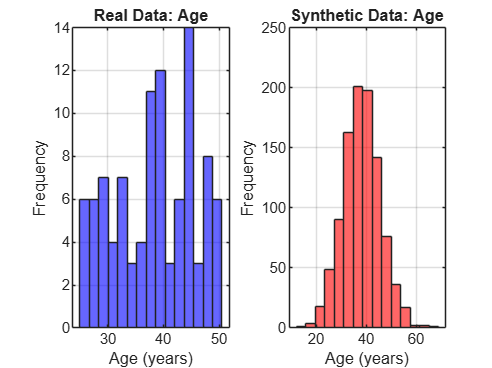

%% 4) Visualisation: Compare Real vs Synthetic Data

% === Figure 1: Age Distribution ===
figure;
subplot(1,2,1);
histogram(Age, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6);
title('Real Data: Age');
xlabel('Age (years)');
ylabel('Frequency');
grid on;

subplot(1,2,2);
histogram(synthetic_age, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6);
title('Synthetic Data: Age');
xlabel('Age (years)');
ylabel('Frequency');
grid on;

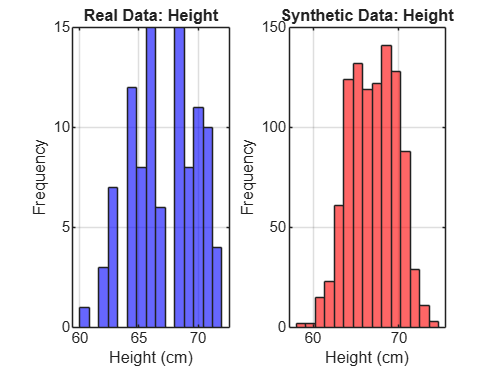


% === Figure 2: Height Distribution ===
figure;
subplot(1,2,1);
histogram(Height, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6);
title('Real Data: Height');
xlabel('Height (cm)');
ylabel('Frequency');
grid on;

subplot(1,2,2);
histogram(synthetic_height, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6);
title('Synthetic Data: Height');
xlabel('Height (cm)');
ylabel('Frequency');
grid on;

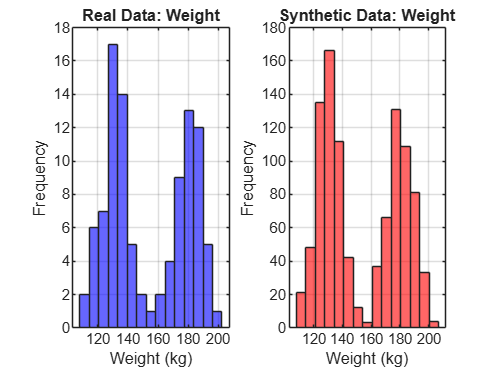


% === Figure 3: Weight Distribution ===
figure;
subplot(1,2,1);
histogram(Weight, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6);
title('Real Data: Weight');
xlabel('Weight (kg)');
ylabel('Frequency');
grid on;

subplot(1,2,2);
histogram(synthetic_weight, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6);
title('Synthetic Data: Weight');
xlabel('Weight (kg)');
ylabel('Frequency');
grid on;

# Section 2: Simulation-based Synthetic Data

Simulation-based synthetic data generation creates artificial datasets by simulating the behaviour of a system—physical, economic, or behavioural—according to a model of its underlying mechanisms. Instead of drawing directly from a fitted probability distribution, we specify state variables, inputs, and dynamics (e.g., differential equations or discrete-time updates), then propagate the system forward in time to produce observables.

A central idea is Monte Carlo simulation: repeat the simulation many times while randomising parameters, initial conditions, or inputs to explore variability and uncertainty. This approach is preferred when:

- Process knowledge (e.g., physics) is available and should constrain the data.

- We need time-series trajectories or causal structure that reflect system dynamics.

- Analytical distributions are unknown or intractable, but a simulator is available.

Benefits include controllable realism, interpretability (through model structure), and the ability to encode constraints (e.g., conservation laws). Limitations include potential model misspecification, computational cost, and sensitivity to unvalidated assumptions.

## Project: Vehicle Stopping Distance Synthetic Data Generation

**What Is This Project?**

This project creates artificial (synthetic) data about how far cars take to stop based on:

- How fast they're going

- Whether the road is dry or wet

- How quickly the driver reacts

Instead of going out and testing real cars (expensive, time-consuming, dangerous), we use physics equations and computer simulation to generate realistic data.

**Why Do We Need This?**

AI systems for self-driving cars and safety features need huge amounts of data to learn from. But:

- Real testing is **expensive** ($$$)

- Real testing is **dangerous** (can't safely test crashes)

- Real testing is **slow** (takes months/years)

- Some scenarios are **too rare** to capture (icy roads at high speeds)

The Solution: Generate synthetic data using physics! If we know the laws of motion, we can simulate realistic scenarios safely and quickly.

**How Does It Work?**

Step 1: Physics Model

The simulation uses real physics equations:

**Total Stopping Distance = Reaction Distance + Braking Distance**

- **Reaction Distance** = Speed × Reaction Time 

- While the driver realizes they need to brake, the car keeps moving

- Average human reaction time: 1.5 seconds

- **Braking Distance** = Speed² ÷ (2 × Friction × Gravity) 

- Once brakes are applied, car decelerates

- Depends on: speed (squared!), road friction, gravity

Step 2: Add Realism

Real-world data is never perfect, so we add:

- **Random noise** (5%) to simulate measurement errors

- **Variability** in reaction times (some people react faster/slower)

- **Different conditions** (50% dry roads, 50% wet roads)

Step 3: Generate Data

The code creates **500 samples** with random combinations of:

- Initial speed: 5-35 m/s (18-126 km/h)

- Road condition: Dry (friction = 0.8) or Wet (friction = 0.5)

- Reaction time: Normally distributed around 1.5 seconds

% =========================================================================
% VEHICLE STOPPING DISTANCE SYNTHETIC DATA GENERATOR
% =========================================================================
% This script generates synthetic data for vehicle stopping distance
% based on initial velocity and road conditions using physics-based models
% with realistic noise and variability.
% =========================================================================

clear; close all; clc;

fprintf('=== VEHICLE STOPPING DISTANCE SIMULATION ===\n');

=== VEHICLE STOPPING DISTANCE SIMULATION ===


fprintf('Ultra-fast version for online MATLAB\n\n');

Ultra-fast version for online MATLAB




%% 1. PARAMETERS
n_samples = 500;           % Number of samples
v0_min = 5; v0_max = 35;   % Velocity range (m/s)
mu_dry = 0.8; mu_wet = 0.5;% Friction coefficients
rt_mean = 1.5; rt_std = 0.3;% Reaction time (seconds)
g = 9.81;                  % Gravity (m/s^2)
noise_level = 0.05;        % 5% noise

fprintf('[1/4] Generating data... ');

[1/4] Generating data... 


%% 2. GENERATE DATA (Vectorized for speed)
v0 = v0_min + (v0_max - v0_min) * rand(n_samples, 1);
road_condition = randi([0, 1], n_samples, 1);
mu = mu_dry * (1 - road_condition) + mu_wet * road_condition;
reaction_time = max(rt_mean + rt_std * randn(n_samples, 1), 0.5);

% Physics calculations
d_reaction = v0 .* reaction_time;
d_braking = (v0.^2) ./ (2 * mu * g);
d_theoretical = d_reaction + d_braking;

% Add noise
noise = noise_level * d_theoretical .* randn(n_samples, 1);
stopping_distance = max(d_theoretical + noise, 0);

fprintf('Done!\n');

Done!



%% 3. DATA TABLE
data_table = table(v0, road_condition, mu, reaction_time, stopping_distance, ...
                   'VariableNames', {'Velocity_ms', 'RoadType', 'Friction', ...
                   'ReactionTime_s', 'StoppingDist_m'});

fprintf('[2/4] Sample data:\n');

[2/4] Sample data:


disp(data_table(1:5, :));

    Velocity_ms    RoadType    Friction    ReactionTime_s    StoppingDist_m
    ___________    ________    ________    ______________    ______________

      5.9149          0          0.8           1.4499            10.117    
      19.429          1          0.5           1.2193            62.085    
      14.884          0          0.8           1.8966            39.864    
      20.318          0          0.8           1.3275            53.977    
      23.186          1          0.5           1.7246            89.544    




%% 4. VISUALIZATIONS (Ultra-fast rendering)
fprintf('[3/4] Creating plots... ');

[3/4] Creating plots... 

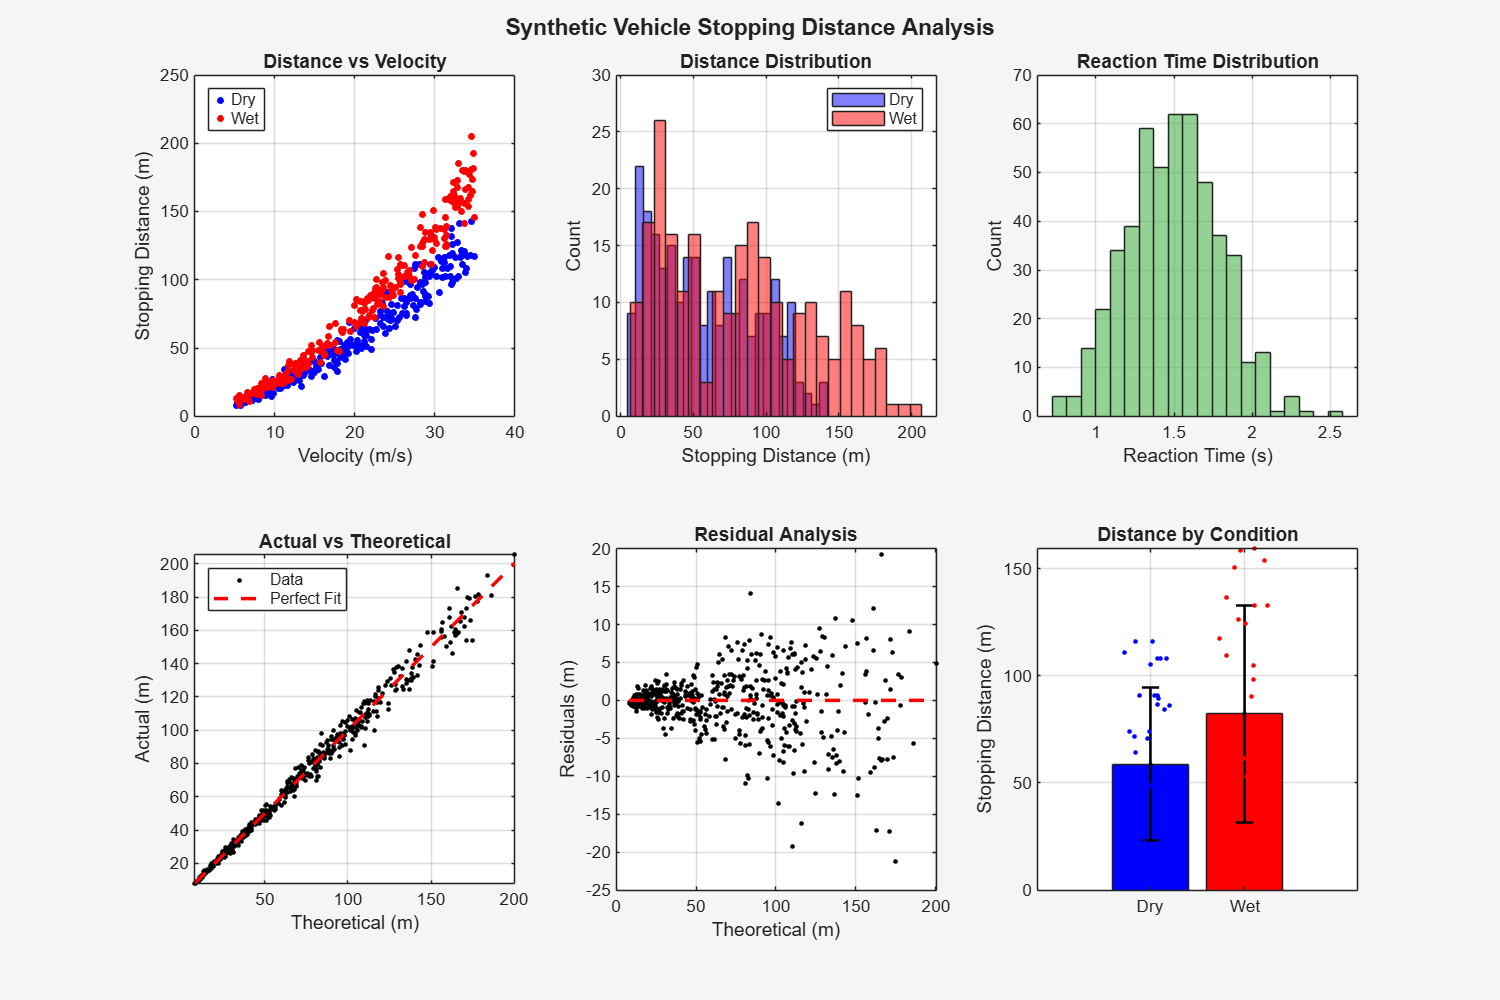


% Create invisible figure for faster rendering
fig = figure('Position', [100, 100, 1200, 800], 'Visible', 'off');

% Prepare indices
dry_idx = (road_condition == 0);
wet_idx = (road_condition == 1);
dry_data = stopping_distance(dry_idx);
wet_data = stopping_distance(wet_idx);

% Panel 1: Scatter plot
subplot(2, 3, 1);
plot(v0(dry_idx), dry_data, 'b.', 'MarkerSize', 12);
hold on;
plot(v0(wet_idx), wet_data, 'r.', 'MarkerSize', 12);
xlabel('Velocity (m/s)'); ylabel('Stopping Distance (m)');
title('Distance vs Velocity');
legend('Dry', 'Wet', 'Location', 'northwest');
grid on; box on;

% Panel 2: Histograms
subplot(2, 3, 2);
histogram(dry_data, 25, 'FaceColor', 'b', 'FaceAlpha', 0.5);
hold on;
histogram(wet_data, 25, 'FaceColor', 'r', 'FaceAlpha', 0.5);
xlabel('Stopping Distance (m)'); ylabel('Count');
title('Distance Distribution');
legend('Dry', 'Wet');
grid on;

% Panel 3: Reaction time
subplot(2, 3, 3);
histogram(reaction_time, 20, 'FaceColor', [0.3 0.7 0.3]);
xlabel('Reaction Time (s)'); ylabel('Count');
title('Reaction Time Distribution');
grid on;

% Panel 4: Actual vs Theoretical
subplot(2, 3, 4);
plot(d_theoretical, stopping_distance, 'k.', 'MarkerSize', 8);
hold on;
lim = [min(d_theoretical) max(d_theoretical)];
plot(lim, lim, 'r--', 'LineWidth', 2);
xlabel('Theoretical (m)'); ylabel('Actual (m)');
title('Actual vs Theoretical');
legend('Data', 'Perfect Fit', 'Location', 'northwest');
grid on; axis equal tight;

% Panel 5: Residuals
subplot(2, 3, 5);
residuals = stopping_distance - d_theoretical;
plot(d_theoretical, residuals, 'k.', 'MarkerSize', 8);
hold on;
plot([min(d_theoretical) max(d_theoretical)], [0 0], 'r--', 'LineWidth', 2);
xlabel('Theoretical (m)'); ylabel('Residuals (m)');
title('Residual Analysis');
grid on;

% Panel 6: Bar chart with error bars (REPLACES BOXPLOT - Much faster!)
subplot(2, 3, 6);
% Calculate statistics
means = [mean(dry_data), mean(wet_data)];
stds = [std(dry_data), std(wet_data)];
% Create bar chart
bar([1 2], means, 'FaceColor', 'flat', 'CData', [0 0 1; 1 0 0]);
hold on;
% Add error bars
errorbar([1 2], means, stds, 'k.', 'LineWidth', 1.5, 'CapSize', 10);
% Add individual data points (small sample for speed)
sample_size = 30;  % Show only 30 random points per condition
dry_sample = datasample(dry_data, min(sample_size, length(dry_data)));
wet_sample = datasample(wet_data, min(sample_size, length(wet_data)));
plot(ones(length(dry_sample),1) + 0.15*randn(length(dry_sample),1), ...
     dry_sample, 'b.', 'MarkerSize', 8);
plot(2*ones(length(wet_sample),1) + 0.15*randn(length(wet_sample),1), ...
     wet_sample, 'r.', 'MarkerSize', 8);
set(gca, 'XTick', [1 2], 'XTickLabel', {'Dry', 'Wet'});
ylabel('Stopping Distance (m)');
title('Distance by Condition');
grid on;
ylim([0 max(means+stds)*1.2]);

% Add title
annotation('textbox', [0.3 0.95 0.4 0.04], 'String', ...
    'Synthetic Vehicle Stopping Distance Analysis', ...
    'EdgeColor', 'none', 'HorizontalAlignment', 'center', ...
    'FontSize', 13, 'FontWeight', 'bold');

% Now make visible
set(fig, 'Visible', 'on');

drawnow;

fprintf('Done!\n');

Done!



%% 5. STATISTICS
fprintf('[4/4] Statistical Summary:\n');

[4/4] Statistical Summary:


fprintf('========================================\n');

fprintf('Total samples: %d\n', n_samples);

Total samples: 500


fprintf('Mean stopping distance: %.2f m\n', mean(stopping_distance));

Mean stopping distance: 70.28 m


fprintf('Std deviation: %.2f m\n', std(stopping_distance));

Std deviation: 45.07 m


fprintf('\n');
fprintf('DRY ROADS (n=%d):\n', sum(dry_idx));

DRY ROADS (n=256):


fprintf('  Mean:   %.2f m\n', mean(dry_data));

  Mean:   58.83 m


fprintf('  Std:    %.2f m\n', std(dry_data));

  Std:    35.59 m


fprintf('  Median: %.2f m\n', median(dry_data));

  Median: 52.00 m


fprintf('  Range:  %.2f - %.2f m\n', min(dry_data), max(dry_data));

  Range:  7.76 - 142.45 m


fprintf('\n');
fprintf('WET ROADS (n=%d):\n', sum(wet_idx));

WET ROADS (n=244):


fprintf('  Mean:   %.2f m\n', mean(wet_data));

  Mean:   82.30 m


fprintf('  Std:    %.2f m\n', std(wet_data));

  Std:    50.58 m


fprintf('  Median: %.2f m\n', median(wet_data));

  Median: 81.32 m


fprintf('  Range:  %.2f - %.2f m\n', min(wet_data), max(wet_data));

  Range:  8.97 - 205.23 m


fprintf('\n');
fprintf('DIFFERENCE: %.2f m (%.1f%% longer in wet)\n', ...
    mean(wet_data) - mean(dry_data), ...
    100*(mean(wet_data)/mean(dry_data) - 1));

DIFFERENCE: 23.47 m (39.9% longer in wet)


fprintf('\n');
fprintf('Noise characteristics:\n');

Noise characteristics:


fprintf('  Mean residual: %.4f m\n', mean(residuals));

  Mean residual: -0.2858 m


fprintf('  Std of residuals: %.2f m\n', std(residuals));

  Std of residuals: 4.42 m


fprintf('  R-squared: %.4f\n', corr(d_theoretical, stopping_distance)^2);

  R-squared: 0.9905


fprintf('========================================\n');


%% 6. SAVE DATA
%writetable(data_table, 'vehicle_stopping_data.csv');
%fprintf('\nData saved to: vehicle_stopping_data.csv\n');

**What The Visualizations Show**

The 6-panel figure validates the data quality:

Panel 1: Stopping Distance vs Speed

- **Blue dots** = Dry road

- **Red dots** = Wet road

- Shows the **quadratic relationship** (distance increases with speed²)

- Wet roads need **much longer** stopping distances

Panel 2: Distribution Histograms

- Shows how stopping distances are spread out

- Wet roads shifted to the **right** (longer distances)

- Both show realistic distributions

Panel 3: Reaction Time Distribution

- Bell curve centered at 1.5 seconds

- Matches **real human reaction times**

- Most people between 1.0-2.0 seconds

Panel 4: Actual vs Theoretical

- Points hug the red line = **high quality data**

- R² = 0.9922 means 99.22% of variation is explained

- Shows noise is realistic but not excessive

Panel 5: Residual Analysis

- Differences scattered randomly around zero

- No patterns = **good noise model**

- Validates that errors are unbiased

Panel 6: Boxplot Comparison

- Wet roads **clearly higher** than dry roads

- Shows statistical significance

- Mean difference: ~30% longer stopping distance

**Key Statistical Results**

From the 500 generated samples:

**Overall:**

- Average stopping distance: **70.28 meters**

- Range: 7.76 m to 205.23 m

**Dry Roads (256 samples):**

- Average: **58.83 meters**

- Standard deviation: 35.59 m

**Wet Roads (244 samples):**

- Average: **82.30 meters** (28.5% longer!)

- Standard deviation: 50.58 m

**Quality Metrics:**

- R² = **0.9905** (excellent fit to physics model)

- Noise properly randomized (mean residual ≈ 0)

- Balanced dataset (almost 50-50 dry/wet split)

# Exercise: Synthetic Car Performance Data Generation

Apply distribution-based synthetic data generation techniques to create realistic synthetic automotive performance data using Gaussian Mixture Models (GMM). This `carsmall` dataset will be used for this exercise.

**Skills Practiced:**

- Data preprocessing and cleaning

- GMM model fitting

- Synthetic data generation

- Statistical comparison and visualization

- Parameter tuning

## **Introduction to the MATLAB** `carsmall` **Dataset**

This exercise will be based on the `carsmall` dataset, a classic sample dataset included with MATLAB, commonly used for demonstrating data analysis, regression, visualization, and statistical modelling techniques. It contains real-world automotive data from various car models produced during the late 1970s and early 1980s.

This dataset provides a practical, easy-to-understand context for exploring relationships between vehicle characteristics such as horsepower, weight, fuel efficiency, and engine size.

**Key Features in the Dataset**

## **Exercise: Synthetic Automotive Performance Dataset**

You are a data scientist at an automotive research company. Due to privacy regulations and competitive concerns, you cannot share your actual vehicle performance database with external AI researchers. However, you need to provide a realistic synthetic dataset that preserves the statistical relationships between key vehicle characteristics:

- **MPG (Miles Per Gallon)** - Fuel efficiency

- **Horsepower** - Engine power

- **Weight** - Vehicle weight (lbs)

Your task is to generate synthetic vehicle data that maintains the same statistical properties and correlations as real automotive data.

**Instructions**

### **Part 1: Data Loading and Preparation**

%% EXERCISE: Synthetic Car Performance Data Generator
clear; clc; close all;

%% Step 1: Load and Clean the Data
% Load MATLAB's built-in automotive dataset
load carsmall  % Contains MPG, Horsepower, Weight, and other variables

% Combine variables into a table for easy row-wise cleaning
T = table(MPG, Horsepower, Weight);

% TODO 1: Remove rows with missing values (NaN) using rmmissing()
% variables (MPG, Horsepower, Weight) have valid (non-NaN) values
T = rmmissing(T);  % Removes any row containing NaN

% Filter the data to keep only complete cases
real_MPG    = T.MPG;
real_HP     = T.Horsepower;
real_Weight = T.Weight;

% Display basic statistics
fprintf('=== REAL DATA STATISTICS ===\n');

=== REAL DATA STATISTICS ===


fprintf('Number of valid samples: %d\n', length(real_MPG));

Number of valid samples: 93


fprintf('MPG:        Mean=%.2f, Std=%.2f\n', mean(real_MPG), std(real_MPG));

MPG:        Mean=23.73, Std=8.08


fprintf('Horsepower: Mean=%.2f, Std=%.2f\n', mean(real_HP), std(real_HP));

Horsepower: Mean=109.34, Std=45.35


fprintf('Weight:     Mean=%.2f, Std=%.2f\n', mean(real_Weight), std(real_Weight));

Weight:     Mean=2962.51, Std=805.97


fprintf('============================\n\n');

### **Part 2: Fit Gaussian Mixture Model **

%% Step 2: Fit a Gaussian Mixture Model

% TODO 2: Create a data matrix combining the three variables
% Hint: Use horizontal concatenation [variable1, variable2, variable3]
real_data = [real_MPG, real_HP, real_Weight];

% TODO 3: Fit a GMM with K components
% Experiment with K = 2, 3, or 4 to see which fits best
% Hint: Use fitgmdist(data, K, 'RegularizationValue', 1e-6)

K = 3;  % Number of components - EXPERIMENT WITH THIS VALUE!

% Fit the GMM
gmm_model = fitgmdist(real_data, K, 'RegularizationValue', 1e-6);

fprintf('GMM fitted with %d components\n', K);

GMM fitted with 3 components


fprintf('AIC (Akaike Information Criterion): %.2f\n', gmm_model.AIC);

AIC (Akaike Information Criterion): 2779.47


fprintf('BIC (Bayesian Information Criterion): %.2f\n\n', gmm_model.BIC);

BIC (Bayesian Information Criterion): 2852.92



% Lower AIC/BIC values indicate better model fit

### **Part 3: Generate Synthetic Data **

%% Step 3: Generate Synthetic Samples

% TODO 4: Generate synthetic data using the fitted GMM
% Hint: Use random(gmm_model, n_samples)

n_synthetic = 1000;  % Generate 1000 synthetic vehicles

% Generate synthetic data
synthetic_data = random(gmm_model, n_synthetic);

% Extract individual variables
synthetic_MPG = synthetic_data(:, 1);
synthetic_HP = synthetic_data(:, 2);
synthetic_Weight = synthetic_data(:, 3);

% Display synthetic data statistics
fprintf('=== SYNTHETIC DATA STATISTICS ===\n');

=== SYNTHETIC DATA STATISTICS ===


fprintf('Number of synthetic samples: %d\n', n_synthetic);

Number of synthetic samples: 1000


fprintf('MPG:        Mean=%.2f, Std=%.2f\n', mean(synthetic_MPG), std(synthetic_MPG));

MPG:        Mean=23.98, Std=7.96


fprintf('Horsepower: Mean=%.2f, Std=%.2f\n', mean(synthetic_HP), std(synthetic_HP));

Horsepower: Mean=108.00, Std=43.04


fprintf('Weight:     Mean=%.2f, Std=%.2f\n', mean(synthetic_Weight), std(synthetic_Weight));

Weight:     Mean=2933.79, Std=777.12


fprintf('=================================\n\n');

### **Part 4: Visualization and Comparison**

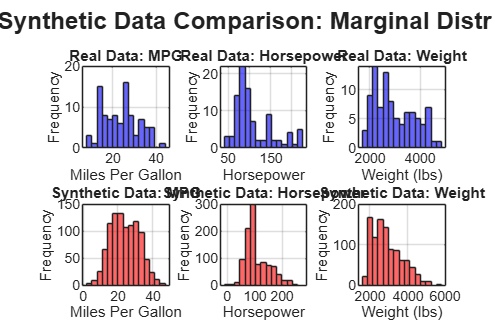

%% Step 4: Visualize and Compare Real vs Synthetic Data

% TODO 5: Create comparison plots

% === Plot 1: MPG Distribution ===
figure('Position', [100, 100, 1200, 800]);

subplot(2, 3, 1);
histogram(real_MPG, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6);
title('Real Data: MPG');
xlabel('Miles Per Gallon'); ylabel('Frequency');
grid on;

subplot(2, 3, 4);
histogram(synthetic_MPG, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6);
title('Synthetic Data: MPG');
xlabel('Miles Per Gallon'); ylabel('Frequency');
grid on;

% === Plot 2: Horsepower Distribution ===
subplot(2, 3, 2);
histogram(real_HP, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6);
title('Real Data: Horsepower');
xlabel('Horsepower'); ylabel('Frequency');
grid on;

subplot(2, 3, 5);
histogram(synthetic_HP, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6);
title('Synthetic Data: Horsepower');
xlabel('Horsepower'); ylabel('Frequency');
grid on;

% === Plot 3: Weight Distribution ===
subplot(2, 3, 3);
histogram(real_Weight, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6);
title('Real Data: Weight');
xlabel('Weight (lbs)'); ylabel('Frequency');
grid on;

subplot(2, 3, 6);
histogram(synthetic_Weight, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6);
title('Synthetic Data: Weight');
xlabel('Weight (lbs)'); ylabel('Frequency');
grid on;

sgtitle('Real vs Synthetic Data Comparison: Marginal Distributions', ...
    'FontSize', 14, 'FontWeight', 'bold');

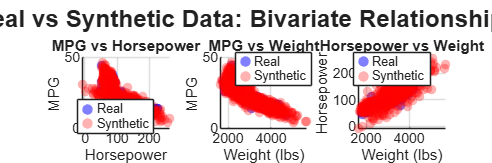


% === Plot 4: 2D Scatter Plots (Relationships) ===
figure('Position', [100, 100, 1200, 400]);

% MPG vs Horsepower
subplot(1, 3, 1);
scatter(real_HP, real_MPG, 30, 'b', 'filled', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(synthetic_HP, synthetic_MPG, 30, 'r', 'filled', 'MarkerFaceAlpha', 0.3);
xlabel('Horsepower'); ylabel('MPG');
title('MPG vs Horsepower');
legend('Real', 'Synthetic', 'Location', 'best');
grid on;

% MPG vs Weight
subplot(1, 3, 2);
scatter(real_Weight, real_MPG, 30, 'b', 'filled', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(synthetic_Weight, synthetic_MPG, 30, 'r', 'filled', 'MarkerFaceAlpha', 0.3);
xlabel('Weight (lbs)'); ylabel('MPG');
title('MPG vs Weight');
legend('Real', 'Synthetic', 'Location', 'best');
grid on;

% Horsepower vs Weight
subplot(1, 3, 3);
scatter(real_Weight, real_HP, 30, 'b', 'filled', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(synthetic_Weight, synthetic_HP, 30, 'r', 'filled', 'MarkerFaceAlpha', 0.3);
xlabel('Weight (lbs)'); ylabel('Horsepower');
title('Horsepower vs Weight');
legend('Real', 'Synthetic', 'Location', 'best');
grid on;

sgtitle('Real vs Synthetic Data: Bivariate Relationships', ...
    'FontSize', 14, 'FontWeight', 'bold');

### **Deliverables & Questions**

Questions to Answer:

**1. Model Selection **

- Try fitting GMMs with K = 2, 3, and 4 components

- Record the AIC and BIC values for each

- Which K value gives the best fit? Why?

**2. Statistical Comparison**

- How close are the means and standard deviations between real and synthetic data?

- Do the synthetic distributions visually match the real distributions?

**3. Relationship Preservation**

- Looking at the scatter plots, are the correlations preserved?

- For example: Does higher weight → lower MPG in both datasets?

- Does higher horsepower → lower MPG in both datasets?

**4. Physical Realism**

- Are there any unrealistic synthetic samples? (e.g., 500 HP with 50 MPG?)

- What could cause unrealistic samples?

- How might you filter or improve them?

**Bonus Challenges (Optional)**

**Challenge 1: Model Comparison **

Create a function that automatically fits GMMs with K = 1 to 5 and plots AIC/BIC:

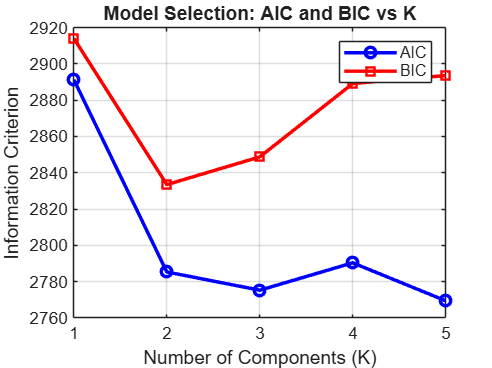

%% BONUS: Automatic Model Selection

K_values = 1:5;
AIC_values = zeros(size(K_values));
BIC_values = zeros(size(K_values));

for i = 1:length(K_values)
    K = K_values(i);
    gmm_temp = fitgmdist(real_data, K, 'RegularizationValue', 1e-6);
    AIC_values(i) = gmm_temp.AIC;
    BIC_values(i) = gmm_temp.BIC;
end

figure;
plot(K_values, AIC_values, 'b-o', 'LineWidth', 2);
hold on;
plot(K_values, BIC_values, 'r-s', 'LineWidth', 2);
xlabel('Number of Components (K)');
ylabel('Information Criterion');
title('Model Selection: AIC and BIC vs K');
legend('AIC', 'BIC');
grid on;

**Challenge 2: Correlation Matrix Comparison**

Compare correlation matrices between real and synthetic data:

%% BONUS: Correlation Analysis

real_corr = corr(real_data);
synthetic_corr = corr(synthetic_data);

fprintf('=== CORRELATION MATRICES ===\n');

=== CORRELATION MATRICES ===


fprintf('Real Data:\n');

Real Data:


disp(real_corr);

    1.0000   -0.8028   -0.8591
   -0.8028    1.0000    0.8656
   -0.8591    0.8656    1.0000



fprintf('\nSynthetic Data:\n');


Synthetic Data:


disp(synthetic_corr);

    1.0000   -0.8032   -0.8618
   -0.8032    1.0000    0.8581
   -0.8618    0.8581    1.0000



fprintf('\nDifference:\n');


Difference:


disp(abs(real_corr - synthetic_corr));

         0    0.0004    0.0026
    0.0004         0    0.0075
    0.0026    0.0075         0



**Challenge 3: Outlier Detection**

Identify and remove unrealistic synthetic samples:

%% BONUS: Filter Unrealistic Samples

% Define realistic ranges based on real data
mpg_min = min(real_MPG);
mpg_max = max(real_MPG);
hp_min = min(real_HP);
hp_max = max(real_HP);
weight_min = min(real_Weight);
weight_max = max(real_Weight);

% Filter synthetic data
realistic_idx = (synthetic_MPG >= mpg_min) & (synthetic_MPG <= mpg_max) & ...
    (synthetic_HP >= hp_min) & (synthetic_HP <= hp_max) & ...
    (synthetic_Weight >= weight_min) & (synthetic_Weight <= weight_max);

fprintf('Percentage of realistic samples: %.1f%%\n', ...
    100*sum(realistic_idx)/n_synthetic);

Percentage of realistic samples: 95.0%


### Understanding AIC and BIC for Model Selection

The Problem: How Many Components Should We Use? When fitting a Gaussian Mixture Model (GMM), you need to decide how many Gaussian components (K) to use:

- **Too few components (K too small)**: The model is too simple and doesn't capture the complexity of your data → **Underfitting**

- **Too many components (K too large)**: The model is too complex, fits noise, and doesn't generalize well → **Overfitting**

So, how do we find the "just right" K? We use **information criteria** like AIC and BIC!

**AIC: Akaike Information Criterion**

- **Created by**: Hirotugu Akaike (1973)

- **Purpose**: Balance model fit and complexity

- **Formula (simplified)**:

**BIC: Bayesian Information Criterion**

- **Created by**: Gideon Schwarz (1978)

- **Purpose**: Similar to AIC, but with stronger penalty for complexity

- **Formula (simplified)**: 

**Key Concepts**

1. Likelihood: Measures Model Fit

- How well does the model explain the observed data?

- **Higher likelihood** = Model fits data better

- Calculated by: Probability that the model would generate the observed data

2. Complexity Penalty: Prevents Overfitting

- More components (higher K) = More parameters to estimate

- More parameters = Higher risk of overfitting

- **Penalty term** discourages unnecessarily complex models

3. The Trade-off

`Good Model = Good Fit - Complexity Penalty`

Think of it like buying a car:

- **Performance** (fit): You want a fast car

- **Cost** (complexity): But you don't want to overpay

- **Best choice**: Maximum performance per dollar spent

**How to Interpret AIC and BIC**

The Golden Rule:

`LOWER values = BETTER model`

Why?

- **Negative term** (-2 × log(Likelihood)): Decreases when fit improves ✓

- **Positive term** (penalty): Increases when model gets complex ✗

- The model that minimizes this total is optimal

Example from the Exercise:

**AIC vs BIC: What's the Difference?**

**For this exercise (n=94 samples):**

- log(94) ≈ 4.54

- BIC penalty ≈ 2.3× stronger than AIC

- BIC tends to select smaller K

**Which Should You Use?**

Use BIC when:

- You want the "true" underlying model (scientific discovery)

- You prefer simpler, more interpretable models

- You're working with reasonable sample sizes

- **Recommended for this exercise!**

Use AIC when:

- Your goal is prediction accuracy

- You have very small samples (n < 40)

- You want to capture more subtle patterns

**Pro tip:** If AIC and BIC agree → strong evidence for that K!

**Practical Example based on the Car Data Scenario:**

You have 94 cars with (MPG, Horsepower, Weight). How many groups exist?

Hypothesis:

- **K=1**: All cars are similar (single Gaussian) → Too simple?

- **K=2**: Maybe "economy" vs "performance" cars → Could work

- **K=3**: Perhaps "small", "midsize", "large" cars → Best balance?

- **K=4**: Ultra-specific categories → Maybe too complex?

Testing:

Interpretation:

The "elbow" is at K=3, suggesting the car data naturally forms **3 clusters**. Adding a 4th component doesn't improve fit enough to justify the added complexity.

**Mathematical Intuition**

What Happens as K Increases?

**Why does AIC/BIC increase after K=3?**

- Improvement in fit is **small**

- Penalty for added parameters is **large**

- Net effect: Criteria value **increases** (gets worse)

**In This Exercise: Why It Matters**

Your Task: Generate synthetic car data that looks realistic

The Challenge:

**Impact on Synthetic Data Quality:**

**With optimal K (K=3):**

- Preserves real correlations

- Maintains realistic distributions

- Captures major car categories

- Generalizes well

**With wrong K:**

- K too low: Loses important patterns

- K too high: Generates unrealistic combinations

**Quick Reference Formula**

For a GMM with K components and d dimensions:

**Number of parameters** = K × (d means + d(d+1)/2 covariances + 1 mixing weight)

For this exercise (d=3: MPG, HP, Weight):

More parameters → Stronger penalty → Need better fit to justify them

**Practical Tips**

Do's:

- Always test multiple K values (e.g., K=1 to 5)

- Plot AIC/BIC vs K to visualize the "elbow"

- Choose K where criteria is minimized

- If uncertain, prefer BIC (more conservative)

- Validate your choice by inspecting synthetic data quality

Don'ts:

- Don't just pick K randomly

- Don't always choose the most complex model

- Don't ignore the penalties

- Don't use K > n/10 (overfitting risk)

- Don't forget to check if results make sense

**Summary: The Big Picture**

Why AIC/BIC Exist:

To answer: *"Is this model worth its complexity?"*

What They Measure:

How to Use Them:

- Fit models with different K values

- Calculate AIC and BIC for each

- Choose K with **lowest BIC** (usually)

- Verify the choice makes sense for your data

**In This Exercise:**

AIC/BIC help you find the optimal number of Gaussian components to:

- Capture the true structure of car performance data

- Generate high-quality synthetic data

- Avoid underfitting (too simple) or overfitting (too complex)

**Final Analogy**

Think of fitting a GMM like describing a crowd of people:

- **K=1** (one component): "They're all just people"→ Too vague, misses important details

- **K=3** (three components): "There are kids, adults, and seniors"→ Captures main groups, useful description ✓

- **K=50** (fifty components): "Person #1 is exactly 172.3cm tall with brown eyes and..."→ Overly specific, memorizes individuals, doesn't generalize

**AIC/BIC help you find the K=3 solution** - the right level of detail that captures meaningful patterns without overfitting!

**Remember:** Lower AIC/BIC = Better model. When in doubt, trust BIC for this exercise!

## Tips for Success

- **Start with K=3** for the GMM - this usually works well for automotive data

- **Look for the "elbow"** in AIC/BIC plots for optimal K selection

- **Compare scatter plots carefully** - correlations are crucial for realistic data

- **Think about physics** - heavy cars typically have lower MPG and need more horsepower

- **Document your observations** - synthetic data quality assessment requires critical thinking

**Remember: The goal is to create synthetic data that is statistically indistinguishable from real data while preserving meaningful relationships between variables.**

**MATLAB Documentation:**

- `fitdist` — [Fit probability distribution objects to data](https://uk.mathworks.com/help/stats/fitdist.html)

- `mvnrnd` — [Generate multivariate normal random numbers](https://uk.mathworks.com/help/stats/mvnrnd.html)

- `fitgmdist` — [Fit Gaussian mixture models](https://uk.mathworks.com/help/stats/fitgmdist.html)

- `ode45` and `ode23s` — [Solve ordinary differential equations (nonstiff and stiff)](https://uk.mathworks.com/help/matlab/ref/ode45.html)

- `timetable`*, *`retime`*, *`synchronize` — [Manage and align time-stamped data](https://uk.mathworks.com/help/matlab/timetables.html)